# 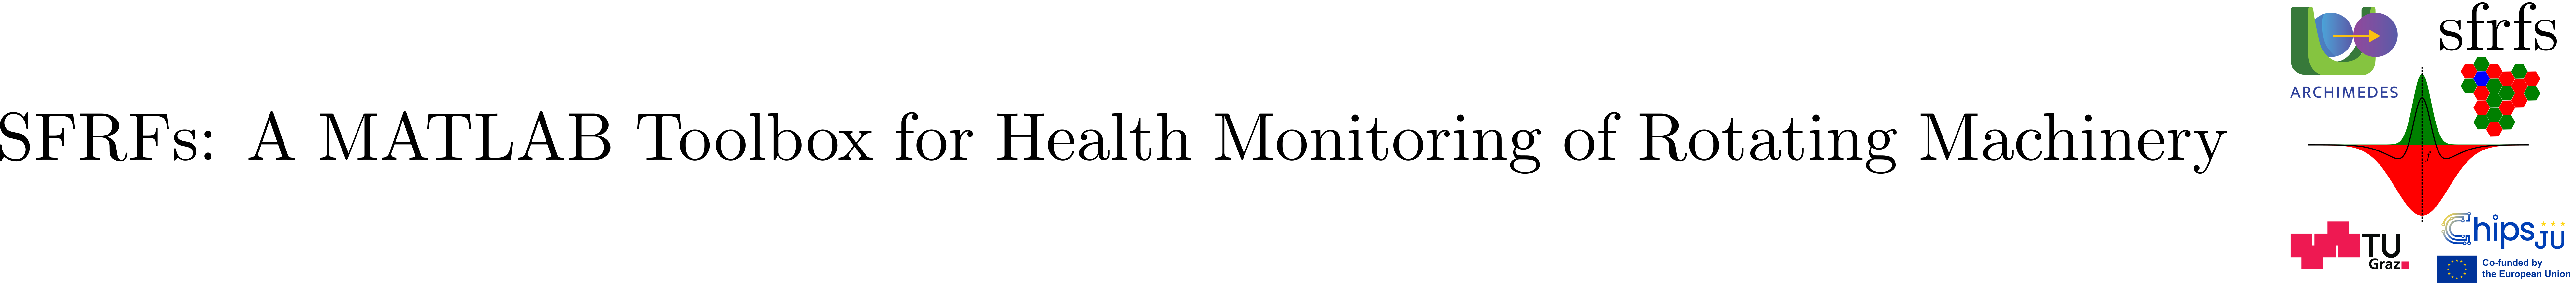

# SFRFsEnsembleProcessor

## Summary

Concrete subclass of `EnsembleProcessor` that processes ensemble data to compute Spectral Fault Receptive Fields.

**Key features**:

- Manages parallel or sequential processing of ensemble members to compute SFRF responses.

- Utilizes input parameters including frequency bands, snapshot details, and receptive field gain functions.

- Computes SFRF responses for each temporal signal column and appends these as new columns in ensemble member tables.

- Validates the presence and correctness of precomputed FFT columns before processing.

- Provides static utility for temporal buffering of SFRFs, stacking response vectors over multiple time steps with NaN padding for missing history.

- Integrates seamlessly with `SFRFsCompute` and `ReceptiveFieldGainFunctions` for modular and extensible computation.

- Constructor requires configuration of the number of workers, ensemble broker, frequency bands, and snapshot parameters.

This class embodies the core ensemble processing workflow for SFRF analysis in the toolbox, leveraging parallel execution and modular component design.

## Description

SFRFsEnsembleProcessor is a concrete processing class that standardizes the computation of Spectral Fault Receptive Field responses across ensemble members. The processor orchestrates both parallel and sequential evaluation of SFRF computations and encapsulates the configuration required to produce frequency band representations and receptive field gain functions. It stores validated references to the ensemble broker, the frequency band definitions, and the snapshot parameters that determine the temporal structuring of the input signals. By centralizing these components, the processor ensures that all downstream SFRF computations rely on a consistent set of spectral and temporal metadata.

The class provides a unified workflow for retrieving processing parameters, validating precomputed spectral data, evaluating SFRFs for each temporal signal column, and extending ensemble member tables with the computed responses. It delegates worker management and bulk iteration to its EnsembleProcessor superclass while injecting a standardized compute method that handles frequency band construction, gain function generation, and spectral masking via SFRFsCompute. 

### Public properties

### Public methods

### Static methods

## Example

SFRFs computation requires precomputing the FFT of the acceleration signals. This can be achieved with the [FFTEnsembleProcessor](matlab:open('./FFTEnsembleProcessor.mlx')) class. Although self contained the following example does not explain all the steps. We refer the reader to the example provided in the respective documentation. 

### Precomputing FFT of vibration signals

% Initialize and prepare EnsembleMock with random members and random
% signals
ensembleMock = EnsembleMock();

% Creates temp folder and saves ensemble files with random data
ensembleMock.prepare();  

% Obtain a handle of fileEnsembleDatastore
ds = ensembleMock.fileEnsembleDS;

% Register ensemble
EnsembleDatastoreRegistry.addEnsemble(...
    name="sfrfs-example",datastore=ds);

% Name of the columns containing the raw signals
temporalSnapshotColumns = {...
    'HorizontalAcceleration', 'VerticalAcceleration'};

% Create broker (base class)
broker = EnsembleBroker( ...
    'ensembleObject', ds, ...
    'getFilesFunction', @(obj) obj.Files, ...
    'temporalSnapshotColumns', temporalSnapshotColumns);

% Creation of the processor
processor = FFTEnsembleProcessor(...
    numWorkers = 5, ...
    ensemble = broker);

% Parallel processing of the members
processor.process();

% Obtain name of FFT computed columns
FFTCols = string(...
    cellfun(@(c) broker.mapToSpectralColumn(c), ...
        temporalSnapshotColumns, ...
        'UniformOutput', false)).';

% Reconfiguring the ensemble to include new columns
ds = EnsembleDatastoreRegistry.reconfigureEnsemble( ...
    name = "sfrfs-example", ...
    DataVariables = [ds.DataVariables(:); FFTCols(:)], ...
    SelectedVariables = [ds.SelectedVariables;FFTCols(:)]);

% Sanity check: read and summarize transformed data
firstMember = read(ds);
summary(firstMember);


firstMember: 10×7 table

Variables:

    SnapshotIndex: double
    HorizontalAcceleration: cell
    VerticalAcceleration: cell
    HorizontalAcceleration_FFT: cell
    VerticalAcceleration_FFT: cell
    Speed: double
    Load: double

Statistics for applicable variables:

                                  NumMissing     Min        Median       Max         Mean          Std    

    SnapshotIndex                     0            1        5.5000        10        5.5000        3.0277  
    HorizontalAcceleration            0                                                                   
    VerticalAcceleration              0                                                                   
    

### Computing SFRFs

We now proceed to compute SRFRs based on the available spectra. The main difference with the previous steps is that we need to define the SFRFs parameters and create a specialized broker and parallel processor.

#### Creation of Bearing SFRFs parameters

% Create SFRFs parameters for bearing faults
% SFRFs order
order = 0;
% number of sidebands
numSidebands = 2;
% number of harmonics
numHarmonics = 10;
% center bandwith (Hz)
centerBandwith = 4;
% center sigma rule
centerSigmaRule = 2;
% center shape parameters
sigmaCenter = [centerBandwith,centerSigmaRule];
% center bandwith (Hz)
surroundBandwith = 3*centerBandwith;
% center sigma rule
surroundSigmaRule = 2;
% center shape parameters
sigmaSurround = [surroundBandwith,surroundSigmaRule];
% inhibition factor
inhibitionFactor = 1/3;
% use static method to define the SFRFs parameters
sfrfsParams = SFRFsParameters.createSFRFsParameters(...
    order=order, ...
    numHarmonics=numHarmonics, ...
    numSidebands=numSidebands, ...
    sigmaCenter=sigmaCenter, ...
    sigmaSurround=sigmaSurround, ...
    inhibitionFactor=inhibitionFactor);

% Same parameters for all bearing fault types
sbp = SFRFsParametersRollingBearings( ...
      SameForAllFaultTypes = sfrfsParams)

sbp =   SFRFsParametersRollingBearings with properties:

                       outerRace: [1×1 struct]
                       innerRace: [1×1 struct]
                            ball: [1×1 struct]
                            cage: [1×1 struct]
      OUTER_RACE_FAULT_TYPE_NAME: 'outerRace'
      INNER_RACE_FAULT_TYPE_NAME: 'innerRace'
            BALL_FAULT_TYPE_NAME: 'ball'
            CAGE_FAULT_TYPE_NAME: 'cage'
                      faultTypes: {'outerRace'  'innerRace'  'ball'  'cage'}
                ORDER_PARAM_NAME: 'order'
        NUM_SIDEBANDS_PARAM_NAME: 'numSidebands'
        NUM_HARMONICS_PARAM_NAME: 'numHarmonics'
         SIGMA_CENTER_PARAM_NAME: 'sigmaCenter'
       SIGMA_SURROUND_PARAM_NAME: 'sigmaSurround'
    INHIBITION_FACTOR_PARAM_NAME: 'inhibitionFactor'
                      sfrfFields: {'order'  'numSidebands'  'numHarmonics'  'sigmaCenter'  'sigmaSurround'  'inhibitionFactor'}


#### SFRFs broker creation

The specialized ensemble broker for SFRFs calculation is [SFRFsEnsembleBroker](matlab:open('./SFRFsEnsembleBroker.mlx')). 

% Recover the fileEnsembleDatastore
ds = EnsembleDatastoreRegistry.getEnsemble("sfrfs-example");
% Initialize the ensemble broker with the obtained ensemble
broker = SFRFsEnsembleBroker( ...
    EnsembleObject=ds, ...
    GetFilesFunction=@(obj) obj.Files, ...
    TemporalSnapshotColumns=temporalSnapshotColumns)

broker =   SFRFsEnsembleBroker with properties:

        sfrfsSuffixInternal: "_SFRFs"
                   ensemble: [1×1 fileEnsembleDatastore]
                  sortField: "SnapshotIndex"
         memberTableVarName: "ensembleMemberTable"
    temporalSnapshotColumns: {'HorizontalAcceleration'  'VerticalAcceleration'}
             spectralSuffix: "_FFT"


#### Snapshot parameters

We specify the snapshot parameters applicable to the [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) rolling bearing run-to-failure dataset. 

% Creates the descriptor for signal snapshots of XJTU-SY dataset
sp = ParametersSnapshot(...
        'samplingFrequency', 25600, ...
        'duration', 1.28, ...
        'stride', 60);

#### Operating conditions

We specify the operating conditions applicable to the [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) rolling bearing run-to-failure dataset. 

% define vector of rotor speeds
speeds = [35; 37.5; 40];
% define vector with system loads
loads  = [12; 11; 10];
% create the operating conditions
oc = OperatingConditions(speeds, loads)

oc =   OperatingConditions with properties:

    conditionsTable: [3×2 table]


#### Bearing geometry

We specify the relevant geometric parameters applicable to the [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) rolling bearing run-to-failure dataset. See [ParametersRollingBearings](matlab:open('./ParametersRollingBearings.mlx')).

% create the parameters for the bearing
bp = ParametersRollingBearings( ...
            'numRollingElements',8, ...
            'ballDiameter',7.92, ...
            'pitchDiameter',34.55, ...
            'contactAngle',0)

bp =   ParametersRollingBearings with properties:

    numRollingElements: 8
          ballDiameter: 7.9200
         pitchDiameter: 34.5500
          contactAngle: 0


#### Bearing fault characteristic frequencies

To compute the fault frequency bands we delegate the calculation to the class [BearingFrequencyBands](matlab:open('./BearingFrequencyBands.mlx')).

% Create monitoring frequency bands for the bearings
bearingFrequencyBands = BearingFrequencyBands( ...
    bearingParams = bp, ...
    sfrfsParams = sbp, ...
    operatingConditions = oc)

bearingFrequencyBands =   BearingFrequencyBands with properties:

            bearingParams: [1×1 ParametersRollingBearings]
                BPFO_CODE: 'Fo'
                BPFI_CODE: 'Fi'
                 BSF_CODE: 'Fb'
                 FTF_CODE: 'Fc'
                  FR_CODE: 'Fr'
      faultFrequencyCodes: {'Fo'  'Fi'  'Fb'  'Fc'}
    faultTypeDescriptions: [4×1 containers.Map]
          faultTypeGroups: [4×1 containers.Map]
     faultGroupToTypeName: [4×1 containers.Map]
              sfrfsParams: [1×1 SFRFsParametersRollingBearings]
      operatingConditions: [1×1 OperatingConditions]
               bandsTable: [0×0 table]


#### SFRFs computation

% Creation of the processor
processor = SFRFsEnsembleProcessor(...
    numWorkers = 5, ...
    ensemble = broker, ...
    frequencyBands = bearingFrequencyBands, ...
    snapshotParameters = sp);

% Parallel processing of the members
processor.process();

% Obtain name of FFT computed columns
SFRFsCols = string(...
    cellfun(@(c) broker.mapToSFRFColumn(c), ...
        temporalSnapshotColumns, ...
        'UniformOutput', false)).';

% Reconfiguring the ensemble to include new columns
ds = EnsembleDatastoreRegistry.reconfigureEnsemble( ...
    name = "sfrfs-example", ...
    DataVariables = [ds.DataVariables(:); SFRFsCols(:)], ...
    SelectedVariables = [ds.SelectedVariables;SFRFsCols(:)]);

% Sanity check: read and summarize transformed data
firstMember = read(ds);
summary(firstMember);


firstMember: 10×9 table

Variables:

    SnapshotIndex: double
    HorizontalAcceleration: cell
    VerticalAcceleration: cell
    HorizontalAcceleration_FFT: cell
    VerticalAcceleration_FFT: cell
    HorizontalAcceleration_SFRFs: cell
    VerticalAcceleration_SFRFs: cell
    Speed: double
    Load: double

Statistics for applicable variables:

                                    NumMissing     Min        Median       Max         Mean          Std    

    SnapshotIndex                       0            1        5.5000        10        5.5000        3.0277  
    HorizontalAcceleration              0                                                                   
    Vert

## API documentation

### MATLAB help

help SFRFsEnsembleProcessor

  SFRFsEnsembleProcessor Processes ensemble data for 
    Spectral Fault Receptive Fields (SFRFs).
 
  This class manages parallel or sequential processing of ensemble members 
  to compute SFRF responses based on input parameters encapsulating 
  frequency bands, snapshot parameters, and receptive field gain functions.
 
 
  Properties:
    frequencyBands      - Object specifying frequency band definitions.
    snapshotParameters  - Object specifying sampling and snapshot details.
 
  Methods:
    compute            - Update a single ensemble member with computed 
                         SFRFs.
    process            - Process all ensemble members.
 
  See also: SFRFsCompute, ReceptiveFieldGainFunctions, EnsembleProcessor
    data.createXJTUSYEnsemble, data.getXJTUSYEnsemble

    Documentation for SFRFsEnsembleProcessor
       doc SFRFsEnsembleProcessor




### MATLAB documentation

doc SFRFsEnsembleProcessor

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The source of this class can be found in [SFRFsEnsembleProcessor](matlab:open('../../SFRFsEnsembleProcessor.m')).

## Test

Unit testing for the class is implemented in [TestSFRFsEnsembleProcessor](matlab:open('../../../tests/TestSFRFsEnsembleProcessor.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestSFRFsEnsembleProcessor');

Running TestSFRFsEnsembleProcessor
..
Done TestSFRFsEnsembleProcessor
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestSFRFsEnsembleProcessor/testProcessFailsWithoutFFT                            | Passed
TestSFRFsEnsembleProcessor/testProcessSucceedsWithFFT                            | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).